## VMD-HD

### Signal

clear all;

filename = "data\12 Anh Tach Hop So\U Mang Nao (Meningioma Tumor)\Tumor3_Skull_Tripped.jpg";

signal = imread(filename);
raw = imnoise(signal,'Gaussian', 0.02);

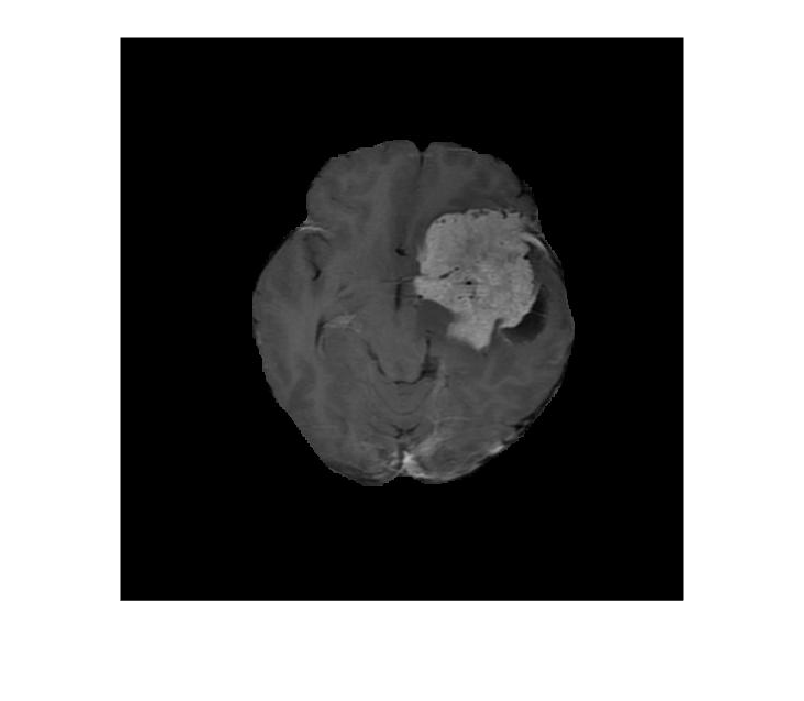

figure('Name','original'), imshow(signal);

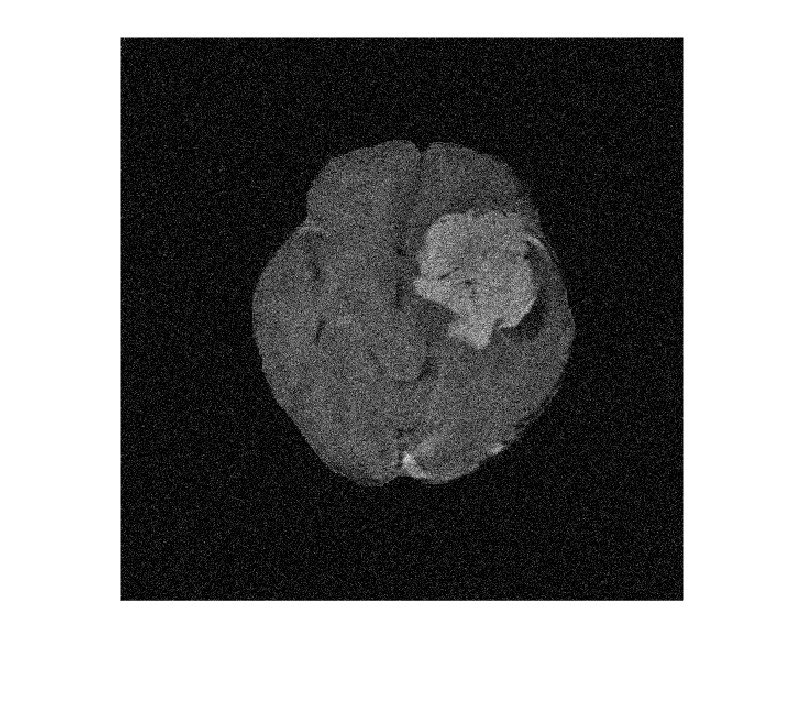

figure('Name','Noisy'), imshow(raw);

psnr_noi=psnr(raw,signal)

psnr_noi = 21.1005

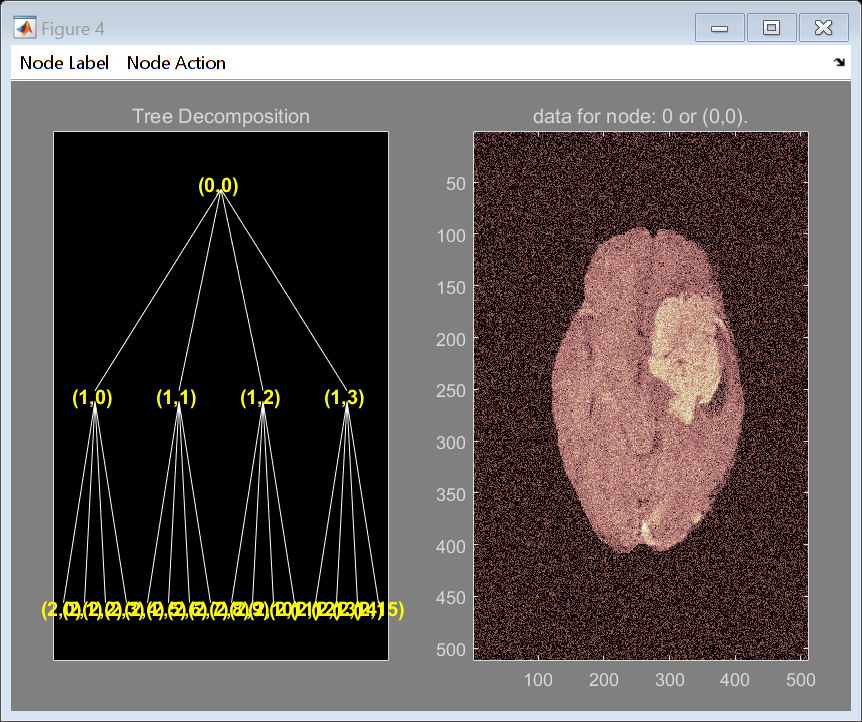


t = wpdec2(double(raw),2,'sym4');
figure('Name','wpk'), plot(t)

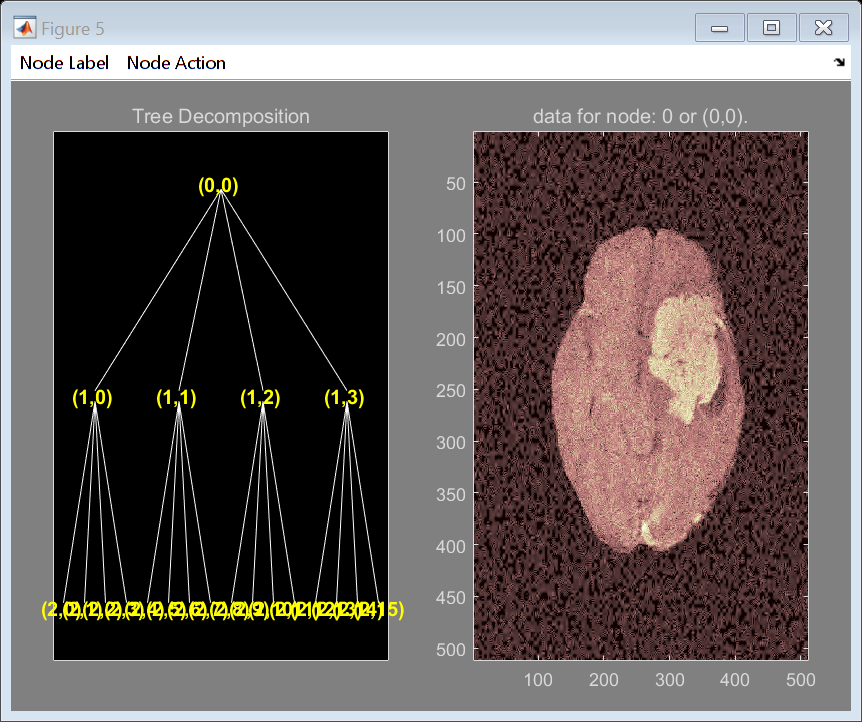

t1=t;
sorh = 'h';
thr = wthrmngr('wp2dcompGBL','bal_sn',t);
cfs = read(t,'data');
cfs = wthresh(cfs,sorh,thr);
t1  = write(t1,'data',cfs);
figure(4), plot(t1)

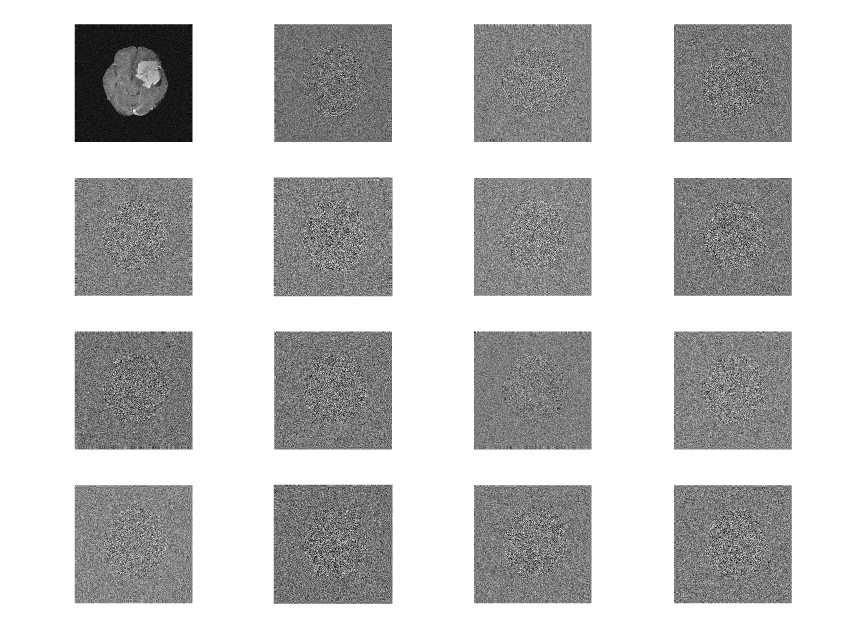

tn  = leaves(t);
u = [];
figure(5)
tile = tiledlayout(length(tn)/4,4);
tile.TileSpacing = 'compact';
tile.Padding = 'compact';
for i = 1:length(tn)
    u(:,:,i) = mat2gray(read(t,'data',tn(i)));
    nexttile;
    cfsn = u(:,:,i);
    imshow(cfsn)
end

% t1 = t;
% sorh = 's';
% tn  = leaves(t);
% for k=1:length(tn)
%   node = tn(k);
%   if k ~=1
%       cfs1 = read(t,'data',node); %khg morph cfs
%       thr = thselect(cfs1(:),'rigrsure');
%       %numthr = rem(node,2)+1;
%       cfs = cfs1;%morph(cfs1); %them do tuong phan 48.26 , morph 48,09 ding wigted average ,hist con 37
%       cfs = wthresh(cfs,sorh,thr);
%       % cfs=medfilt2(uint8(cfs1));
%       % [h,k]=hist((cfs));
%   else
%     cfs = read(t,'data',node);    
%   end
%   t1 = write(t1,'data',node,cfs);
% end	

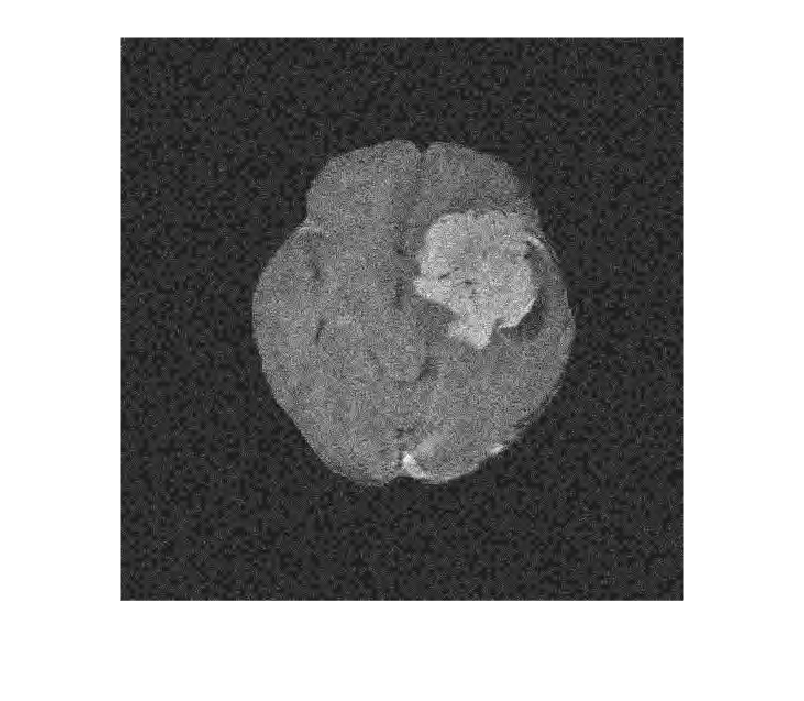

recontruct=wprec2(t1);
figure(6); imshow(mat2gray(recontruct))

psnr_de = psnr(uint8(recontruct),signal)

psnr_de = 24.0300

### PDF

bincount = 255;
disp('paper func')

paper func


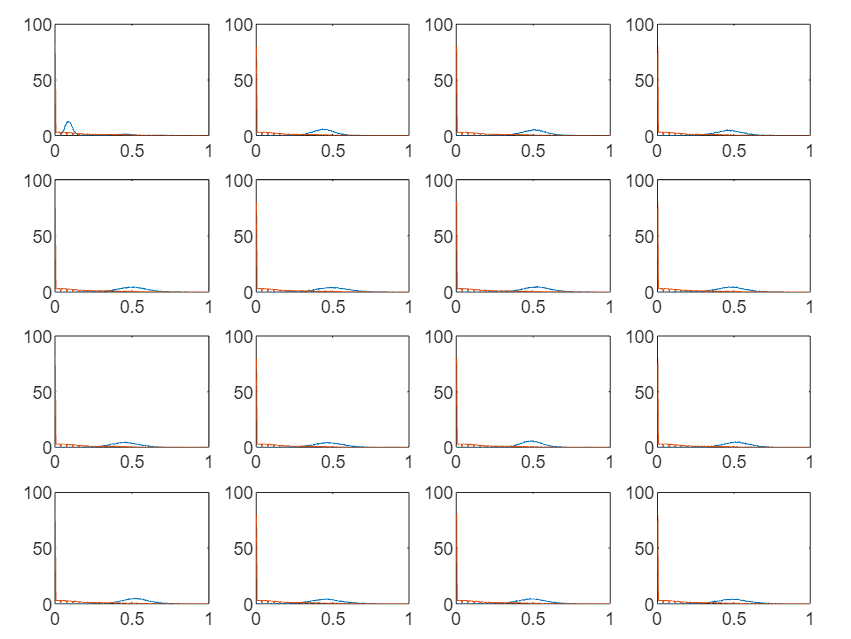

[pdfr,pdfs]=drawIMFhis(mat2gray(double(raw)),u,bincount,'paper');

#### HD

K=length(tn);
distHD=[];
for i = 1:K
    P = pdfr';
    Q = reshape(pdfs(i,:,:),2,[])';
    distHD(i)= hausdorffDist(P,Q);
end

#### l2-norm

distl2=[];
for i = 1:K
    P = pdfr';
    Q = reshape(pdfs(i,:,:),2,[])';
    distl2(i)= l2(P,Q);
end

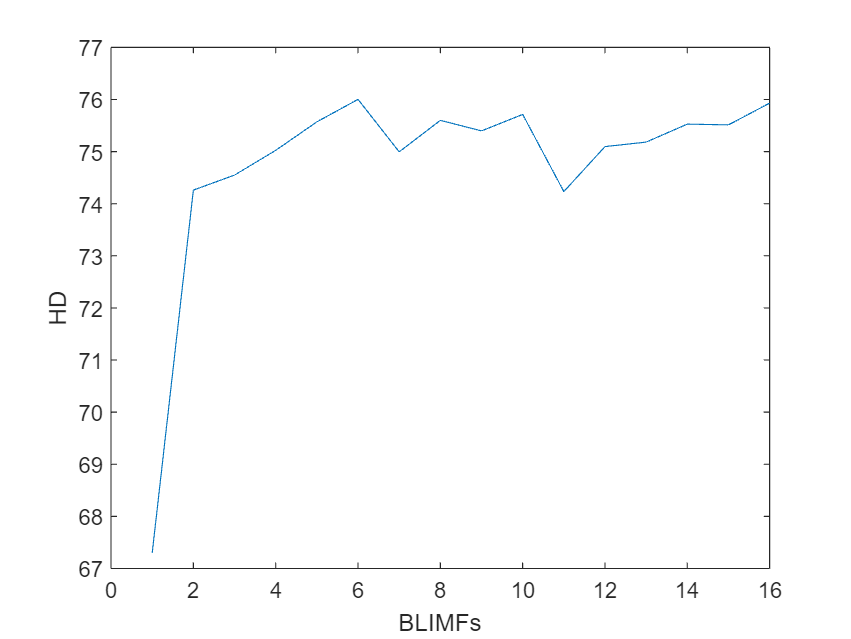

figure('Name','HD');
plot(distHD)
xlabel('BLIMFs')
ylabel('HD')

% hold on
% plot(distl2)
% hold off
% legend(["HD","l2norm"]);

## Maximum slope

disp('by l2');

by l2


[theta,hdi] = max(abs(distl2(1:K-1)-distl2(2:K)))

theta = 1.6845

hdi = 10

% disp('by HD');
% [theta,hdi] = max(abs(distHD(1:K-1)-distHD(2:K)))

## Reconstruct

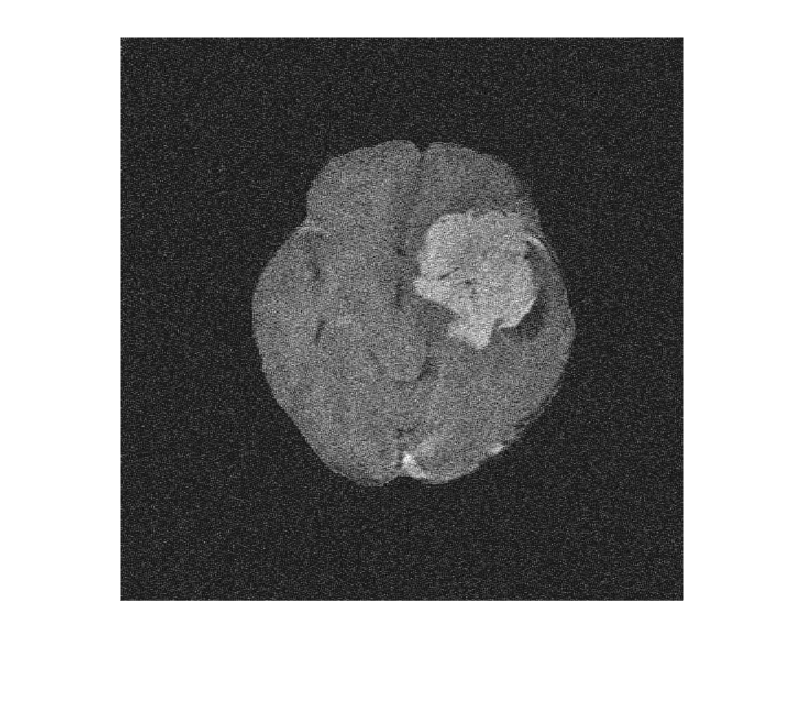

t2= t;
for i = 1:length(tn)
    node = tn(i);
    cfs = read(t,'data',node);
    if i > hdi
        sizec = size(cfs);
        cfs = zeros(sizec(1),sizec(2));   
    end
        t2 = write(t2,'data',node,cfs);
end
recontruct=wprec2(t2);
figure(9); imshow(mat2gray(recontruct))

psnr_de = psnr(uint8(recontruct),signal)

psnr_de = 22.5358

figure('Name','Compare');
plot(t,signal);

Error using findobj
Invalid handle array

Error in ntree/plot (line 135)
        delete(findobj(fig_tree,'Type','axes'));

Error in dtree/plot (line 59)
    fig_tree = plot(t.ntree,class(t),fig_tree);

hold on
plot(t,reconstruct);
hold off
legend(["Orginal","Filtered"]);

### Spectrum

y = fft(reconstruct);
n = length(reconstruct);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y)/n;    % power of the DFT

figure('Name','Filtered fft');
plot(f,power)
xlabel('Frequency')
ylabel('Amplitude')
xlim([0 fs/2])
% set(gca, 'XScale', 'log')

function [ H ] = hausdorffDist(P,Q)
   D = pdist2(P,Q); % Distance calculation
   hab = max(min(D,[],2));% Directed from a to b
   hba = max(min(D));% Directed from b to a
   H = max([hab,hba]);
end

function d = l2(P,Q)
    D = pdist2(P,Q,"euclidean"); % Distance calculation
    sum = 0;
    for i=1:length(D)
        sum = sum+D(i,i)*D(i,i);
    end
    d = sqrt(sum);
end

function arrout = gethisarr(signal,bincount)
    [y,edge] = histcounts(signal,bincount,'Normalization','pdf');
    ne = length(edge);
    x = (edge(2:ne)+edge(1:ne-1))/2;
    arrout = [y;x];
end

function [pdfr,pdfs]=drawIMFhis(raw,u,bincount,name)
    
    pdfr = gethisarr(raw,bincount);
    sizeu = size(u);
    K = sizeu(3);
    pdfs = zeros(K,2,bincount);
    for i = 1:K
        pdfs(i,:,:) = gethisarr(u(:,:,i),bincount);
    end
    figure('Name',"pdf "+name);
    tile = tiledlayout(K/4,4);
    tile.TileSpacing = 'compact';
    tile.Padding = 'compact';
    for i = 1:K
        nexttile;
        plot(reshape(pdfs(i,2,:),1,[]),reshape(pdfs(i,1,:),1,[]));
        hold on;
        plot(pdfr(2,:),pdfr(1,:));
        hold off;
    end
end
